# Train and Simulate DDPG Agent to Balance Human on a Board

% angle limits in degrees
% IMPORTANT: Also change these in the training stopping function
angle_ankle_min = -50;
angle_ankle_max = 50;
angle_knee_min = -135;
angle_knee_max = 0;
angle_hip_min = -10;
angle_hip_max = 110;

u_cutoff = 1;
doTraining = false;
doSave = false;
doLoad = true;
maxepisodes = 8000;
board_freq = 0.5;

param_init;
mdl = "rlHumanMuscleModel";
open_system(mdl)

## Create Environment

obsInfo = rlNumericSpec([11 1])

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [11 1]
       DataType: "double"


actInfo = rlNumericSpec([6 1], "UpperLimit", u_cutoff)

actInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: 1
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [6 1]
       DataType: "double"


env = rlSimulinkEnv(mdl, mdl + "/RL Agent", obsInfo, actInfo)

env = <a href=""matlab: help rl.env.SimulinkEnvWithAgent"">SimulinkEnvWithAgent</a> with properties:

           Model : rlHumanMuscleModel
      AgentBlock : rlHumanMuscleModel/RL Agent
        ResetFcn : []
  UseFastRestart : on


The environment has a continuous action space where the agent can activate each muscle individually. 

obsInfo

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [11 1]
       DataType: "double"


actInfo

actInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: 1
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [6 1]
       DataType: "double"


Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts = 0.02;
Tf = 20;

Fix the random generator seed for reproducibility.

rng(0)

## Create DDPG Agent

% Define path for the state input
statePath = [
    featureInputLayer(prod(obsInfo.Dimension),Name="NetObsInLayer")
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(200,Name="sPathOut")];

% Define path for the action input
actionPath = [
    featureInputLayer(prod(actInfo.Dimension),Name="NetActInLayer")
    fullyConnectedLayer(200,Name="aPathOut",BiasLearnRateFactor=0)];

% Define path for the critic output (value)
commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(1,Name="CriticOutput")];

% Create layerGraph object and add layers
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);

% Connect paths and convert to dlnetwork object
criticNetwork = connectLayers(criticNetwork,"sPathOut","add/in1");
criticNetwork = connectLayers(criticNetwork,"aPathOut","add/in2");
criticNetwork = dlnetwork(criticNetwork);

Display the number of weights and plot the network configuration.

summary(criticNetwork)

   Initialized: true

   Number of learnables: 28.9k

   Inputs:
      1   'NetObsInLayer'   11 features
      2   'NetActInLayer'   6 features



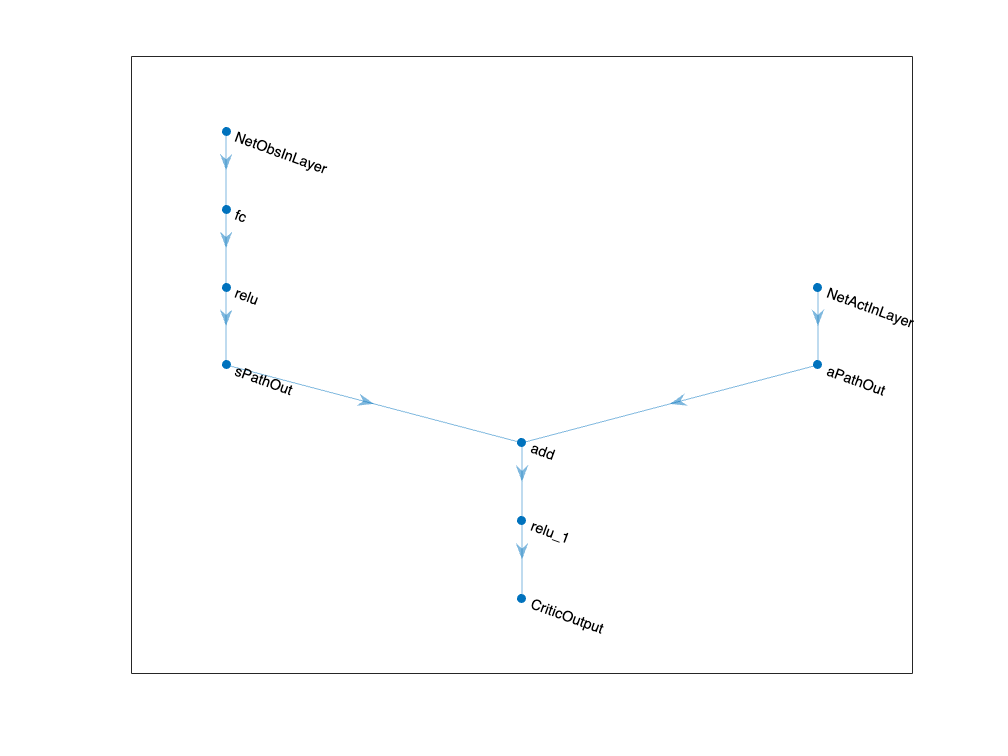

plot(criticNetwork)

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation information for the critic, which you already obtained from the environment interface. For more information, see [rlQValueFunction](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

critic = rlQValueFunction(criticNetwork, ...
    obsInfo,actInfo,...
    ObservationInputNames="NetObsInLayer", ...
    ActionInputNames="NetActInLayer");

DDPG agents use a parametrized deterministic policy over continuous action spaces, which is learned by a continuous deterministic actor. This actor takes the current observation as input and returns as output an action that is a deterministic function of the observation.

actorNetwork = [
    featureInputLayer(prod(obsInfo.Dimension))
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(400)
    reluLayer
    fullyConnectedLayer(prod(actInfo.Dimension))
    tanhLayer
    scalingLayer(Scale=max(actInfo.UpperLimit))
    ];

Convert to dlnetwork and display the number of weights.

actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 108.2k

   Inputs:
      1   'input'   11 features



actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

Specify training options for the critic and the actor using `rlOptimizerOptions`.

criticOptions = rlOptimizerOptions(LearnRate=1e-03,GradientThreshold=1);
actorOptions = rlOptimizerOptions(LearnRate=5e-04,GradientThreshold=1);

Specify the DDPG agent options using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c), and include the training options for the actor and critic.

agentOptions = rlDDPGAgentOptions(...
    SampleTime=Ts,...
    ActorOptimizerOptions=actorOptions,...
    CriticOptimizerOptions=criticOptions,...
    ExperienceBufferLength=1e6,...
    MiniBatchSize=128);

agentOptions.NoiseOptions.Variance = 0.4;
agentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

Create the agent using the actor, critic and agent options objects. For more information, see [`rlDDPGAgent`](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOptions);

## Train Agent

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxsteps = ceil(Tf/Ts);
trainingOptions = rlTrainingOptions(...
    MaxEpisodes=maxepisodes,...
    MaxStepsPerEpisode=maxsteps,...
    ScoreAveragingWindowLength=5,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=4000000,...
    SaveAgentCriteria="EpisodeReward",...
    SaveAgentValue=-400);


Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function.

if doTraining    
    % Train the agent.
    if doLoad
        disp("Load agent")
        load("FinalAgentWeights.mat","agent")
    end
    trainingStats = train(agent,env,trainingOptions);
    if doSave
        save("AgentWeights.mat","agent")
    end
else
    % Load the pretrained agent for the simulation.
    load("FinalAgentWeights.mat","agent")
end

## Simulate DDPG Agent

simOptions = rlSimulationOptions(MaxSteps=50000);
experience = sim(env,agent,simOptions);